clear
clc

% Initializing kero variables
KtL = 10.95; % Tank length in
KtD = 8; % Tank diameter in
KwM = 23.392248; % Wet mass lbm
KdM = 10.992248; % Dry mass lbm
Kdensity = 0.02962444; % Propellant density lbm/in^3 (820 kg/m^3)
Kmdot = 1.24; % Mass flow rate lbm/s

% Initializing lox variables
LtL = 10.95; % Tank length in
LtD = 8; % Tank diameter in
LwM = 28.392248; % Wet mass lbm
LdM = 10.992248; % Dry mass lbm
Ldensity = 0.0416403168; % Propellant density lbm/in^3 (1152.6 kg/m^3)
Lmdot = 1.74; % Mass flow rate lbm/s

% Initializing n2 variables
NtL = 20.4; % Tank Length in
NtD = 6.3; % Tank Diameter in
NwM = 9.92; % Wet mass lbm
NdM = 7.72; % Dry mass lbm
Ndensity = 0.00796751298; % Propellant density lbm/in^3
Nmdot = 0.22; % Mass flow rate lbm/s

time = 10; % Burn time
burntime = linspace(0,time,11);


% Calling function
N2CoGs = getCoG(NwM, NdM, time, NtL, NtD, Ndensity, Nmdot);
T = array2table(N2CoGs,"VariableNames",{'Time (s)','Total Mass (g)','CoG (in from base of tank)','CoG (mm from top of tank)'});
T = table(T,'VariableNames',{'N2 CG'});
disp(T)

                                            N2 CG                                        
    Time (s)    Total Mass (g)    CoG (in from base of tank)    CoG (mm from top of tank)
    _____________________________________________________________________________________

        0           4499.6                  17.379                       76.731          
        1           4399.8                  17.062                       84.788          
        2           4300.1                  16.748                       92.762          
        3           4200.3                  16.437                       100.65          
        4           4100.5                   16.13                       108.45          
        5           4000.7                  15.827                       116.16          
        6           3900.9                  15.527                       123.78        

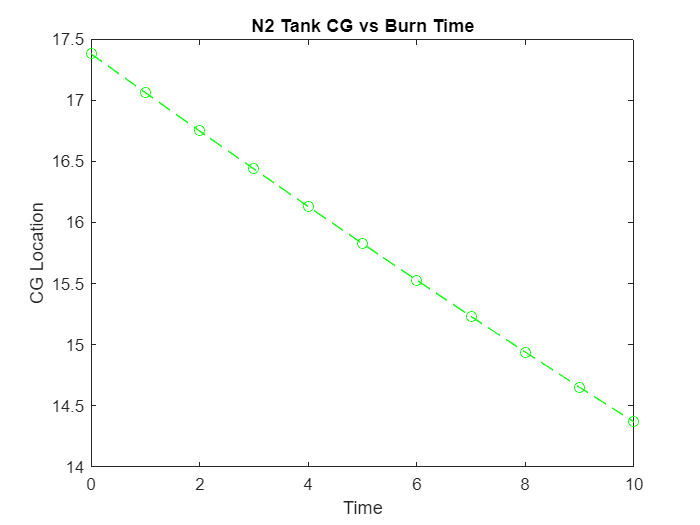

plot(burntime, N2CoGs(:,3),'g--o')
title("N2 Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')


KeroCoGs = getCoG(KwM, KdM, time, KtL, KtD, Kdensity, Kmdot);
T = array2table(KeroCoGs,"VariableNames",{'Time (s)','Total Mass (g)','CoG (in from base of tank)','CoG (mm from top of tank)'});
T = table(T,'VariableNames',{'Kero CG'});
disp(T)

                                           Kero CG                                       
    Time (s)    Total Mass (g)    CoG (in from base of tank)    CoG (mm from top of tank)
    _____________________________________________________________________________________

        0            10611                  7.8954                       77.587          
        1            10048                  7.5746                       85.736          
        2           9485.6                  7.2612                       93.697          
        3           8923.2                  6.9561                       101.45          
        4           8360.7                  6.6604                       108.96          
        5           7798.3                  6.3753                        116.2          
        6           7235.8                  6.1023                       123.13        

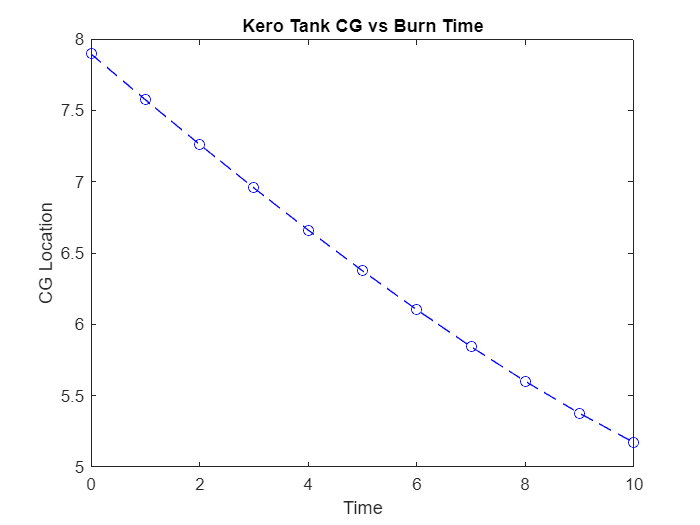

plot(burntime, KeroCoGs(:,3),'b--o')
title("Kero Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')

LOXCoGs = getCoG(LwM, LdM, time, LtL, LtD, Ldensity, Lmdot);
T = array2table(LOXCoGs,"VariableNames",{'Time (s)','Total Mass (g)','CoG (in from base of tank)','CoG (mm from top of tank)'});
T = table(T,'VariableNames',{'LOX CG'});
disp(T)

                                           LOX CG                                        
    Time (s)    Total Mass (g)    CoG (in from base of tank)    CoG (mm from top of tank)
    _____________________________________________________________________________________

        0            12878                  7.1509                       96.496          
        1            12089                  6.8267                       104.73          
        2            11300                  6.5113                       112.74          
        3            10511                   6.206                        120.5          
        4           9721.5                  5.9127                       127.95          
        5           8932.2                  5.6332                       135.05          
        6             8143                  5.3701                       141.73        

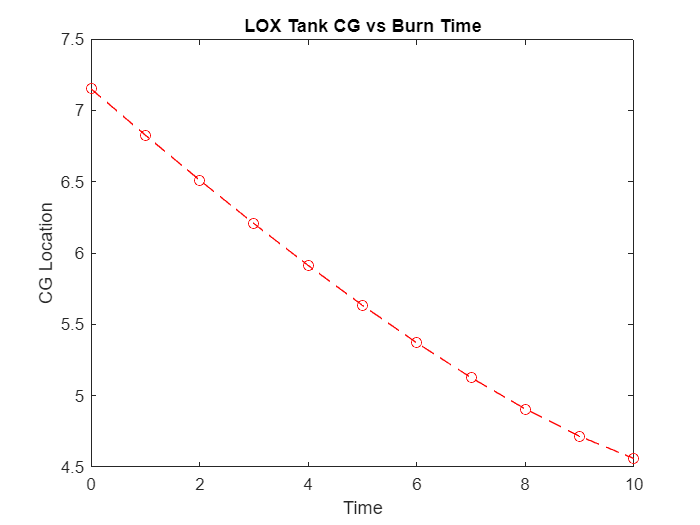

plot(burntime, LOXCoGs(:,3),'r--o')
title("LOX Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')

function [CoGs] = getCoG(wM, dM, time, tL, tD, density, mdot)

Vo = (wM / density) * (1.15); % Finds initial propellant volume
tCG = dM * (tL/2); % Finds constant W1d1/tank term in COG equation
tR = tD / 2; % Converts tank diameter to radius

V = zeros(1,(round(time) + 1)); % Preallocates arrays for variables that change with time
mp = V;
d = V;
COG = V;
COGmm = V;
mpg = V;
% Done preallocating (for now), it's loop time yippee
for t = (0:time)
    mp(t+1) = wM - (mdot * t); % Finds propellant mass at t
    d(t+1) = ((Vo - ((mdot/density)*t)) / (2 * pi * ((tR) ^ 2))); % Finds the distance term for the propellant at t
    COG(t+1) = ((tCG + (mp(t+1) * d(t+1))) / (dM + mp(t+1))); % Finds (finally) the center of gravity at t
    COGmm(t+1) = (tL - COG(t+1)) * 25.4; % Converts CG value to mm from leading edge (needed in .rse file format)
    mpg(t+1) = mp(t+1) * 453.592; % Converts total mass to g (for .rse file creation)
end

CoGs = zeros((round(time) + 1),4); % Preallocates space for CoGs table
CoGs(:,1) = 0:(round(time)); % Makes column of time values
CoGs(:,2) = mpg; % Makes column of total mass values
CoGs(:,3) = COG; % Makes column of CoG values
CoGs(:,4) = COGmm; % Makes column of CoG values for rse files

end